# Machine Learning Model For Cancer Prediction

%reading the dataset
data = readtable('cancer.csv')

data = 569×31 table
    meanRadius    meanTexture    meanPerimeter    meanArea    meanSmoothness    meanCompactness    meanConcavity    meanConcavePoints    meanSymmetry    meanFractalDimension    radiusError    textureError    perimeterError    areaError    smoothnessError    compactnessError    concavityError    concavePointsError    symmetryError    fractalDimensionError    worstRadius    worstTexture    worstPerimeter    worstArea    worstSmoothness    worstCompactness    worstConcavity    worstConcavePoints    

# Exploratory Data Analysis

% statistics
summary(data)


data: 569×31 table

Variables:

    meanRadius: double (mean radius)
    meanTexture: double (mean texture)
    meanPerimeter: double (mean perimeter)
    meanArea: double (mean area)
    meanSmoothness: double (mean smoothness)
    meanCompactness: double (mean compactness)
    meanConcavity: double (mean concavity)
    meanConcavePoints: double (mean concave points)
    meanSymmetry: double (mean symmetry)
    meanFractalDimension: double (mean fractal dimension)
    radiusError: double (radius error)
    textureError: double (texture error)
    perimeterError: double (perimeter error)
    areaError: double (area error)
    smoothnessError: double (smoothness error)
    compactnessError: double (com


% check missing values
sum(ismissing(data))

ans =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



% display first rows from data
head(data)

    meanRadius    meanTexture    meanPerimeter    meanArea    meanSmoothness    meanCompactness    meanConcavity    meanConcavePoints    meanSymmetry    meanFractalDimension    radiusError    textureError    perimeterError    areaError    smoothnessError    compactnessError    concavityError    concavePointsError    symmetryError    fractalDimensionError    worstRadius    worstTexture    worstPerimeter    worstArea    worstSmoothness    worstCompactness    worstConcavity    worstConcavePoints    worstSymmetry</

# Splitting data

X = data{:,1:end-1};
y = data.target;

% Splitting the data into 80% training and 20% testing
cv = cvpartition(y, 'HoldOut', 0.2);
X_train = X(training(cv), :);
X_test = X(test(cv), :);
y_train = y(training(cv), :);
y_test = y(test(cv), :);

% Normalizing the features (standardization)
X_train = (X_train - mean(X_train)) ./ std(X_train);
X_test = (X_test - mean(X_test)) ./ std(X_test);

# Creating and training the model

% Convert the target variable to categorical
y_train_cat = categorical(y_train);  
y_test_cat = categorical(y_test);   

% Create a logistic regression model
model = fitglm(X_train, y_train, 'Distribution', 'binomial');

# Evaluating Performance And accuracy

% Predict the probabilities for the test set (X_test)
y_pred_prob = predict(model, X_test);

% Convert probabilities to class labels (thresholding at 0.5 for binary classification)
y_pred = double(y_pred_prob > 0.5);

% Calculate accuracy
accuracy = sum(y_test == y_pred) / length(y_test);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.95575


# Confusion Matrix

conf_matrix = confusionmat(y_test, y_pred);
disp('Confusion Matrix:');

Confusion Matrix:


disp(conf_matrix);

    41     1
     4    67



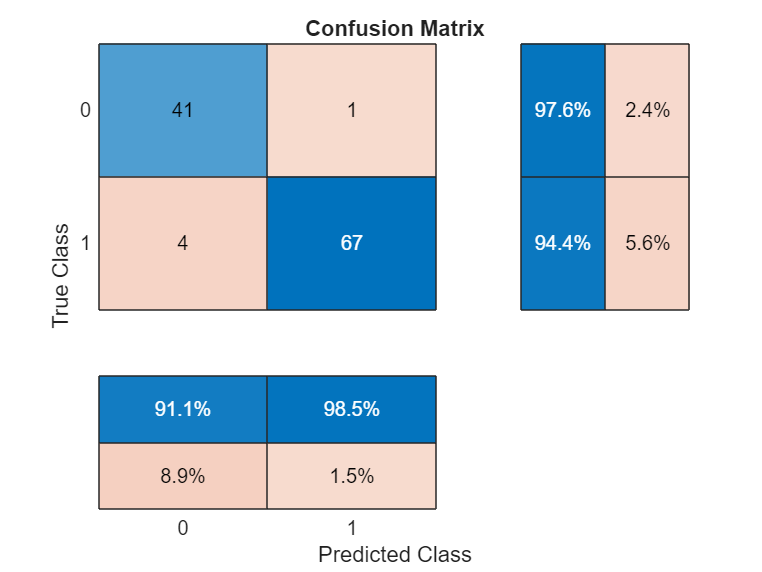


figure;
confusionchart(y_test, y_pred, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');
title('Confusion Matrix');

# Classification Report

TP = conf_matrix(2, 2);
FP = conf_matrix(1, 2);
FN = conf_matrix(2, 1);
TN = conf_matrix(1, 1);

% Compute precision, recall, and F1-score
precision = TP / (TP + FP);
recall = TP / (TP + FN);
f1_score = 2 * (precision * recall) / (precision + recall);

% Display the classification metrics
disp('Classification Report:');

Classification Report:


class_report = table(precision, recall, f1_score);
disp(class_report);

    precision    recall     f1_score
    _________    _______    ________

     0.98529     0.94366    0.96403 



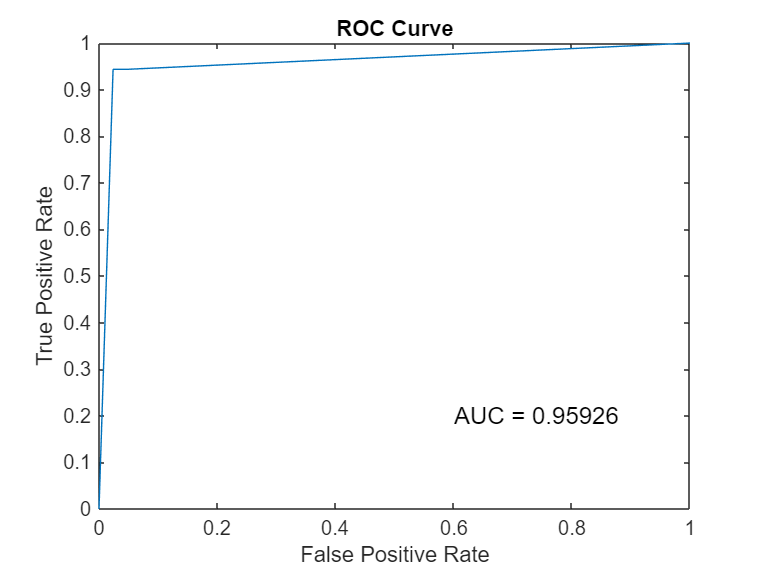


% ROC Curve
[X,Y,T,AUC] = perfcurve(y_test, y_pred_prob, '1');
figure;
plot(X,Y)
title('ROC Curve')
xlabel('False Positive Rate')
ylabel('True Positive Rate')
text(0.6, 0.2, ['AUC = ' num2str(AUC)], 'FontSize', 12)